# N-body system

## 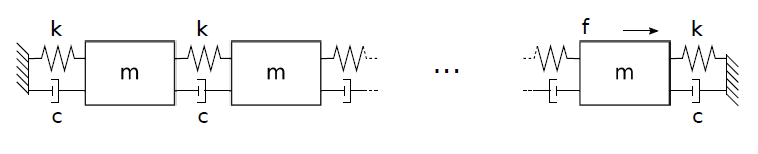

% Allow animating plots in the script (requires >= R2019a)
s = settings;
s.matlab.editor.AllowFigureAnimation.PersonalValue = true;

## System matrices

N = 4; % number of masses
m = 1; % [kg]
k = 16; % [N/m]
c = 1; % [Ns/m]

M = m * eye(N); % mass matrix
K = zeros(N); % stiffness matrix
for i=1:(N-1)
    % elastic forces between a pair of masses
    K_pair = k * [1 -1;
                 -1  1];
    K(i:i+1, i:i+1) = K(i:i+1, i:i+1) + K_pair;
end

## Eigenmodes

Demonstrations for an undamped system

### Clamped-clamped

In this case the first and the last are immobilised, setting $x_1$ and $x_N$ to 0. Therefore first and last row can be removed

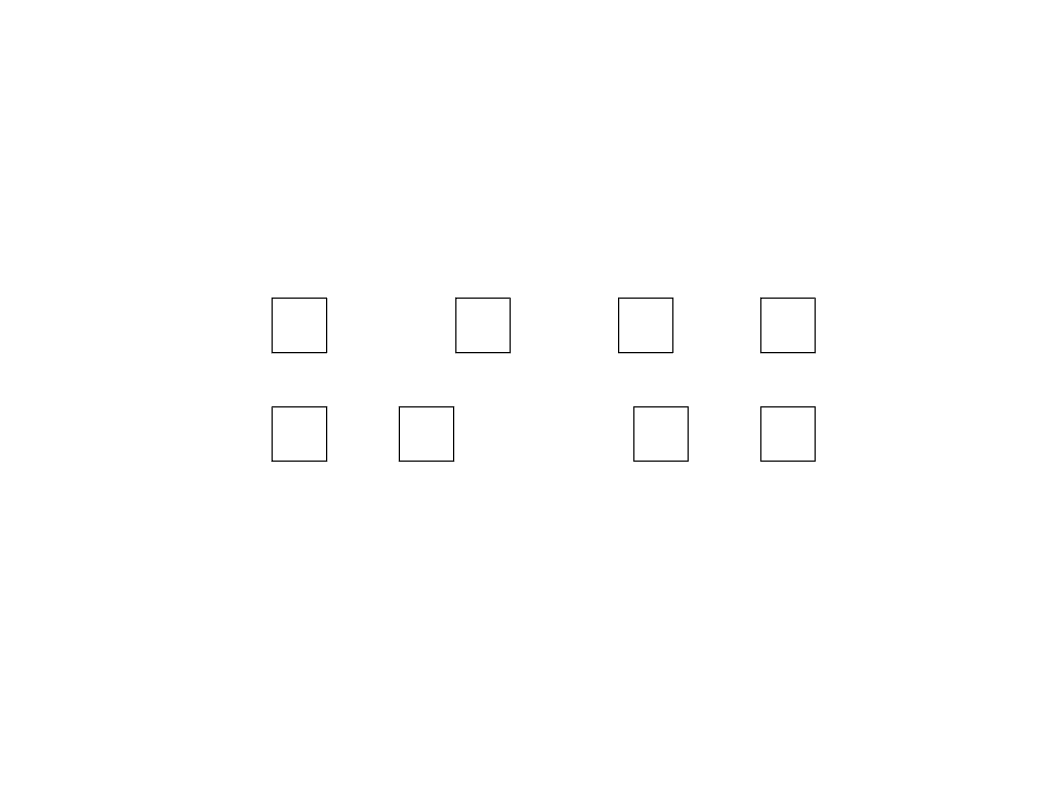

dof = 2:N-1;
ampl = zeros(N);
omega_sq = zeros(N, 1);
[ampl(dof, dof), omega_sq(dof, 1)] = eig(K(dof,dof), M(dof,dof), 'vector');
animate_modes(N, dof, omega_sq, ampl);

### Clamped-free

Now only $x_1$ is fixed

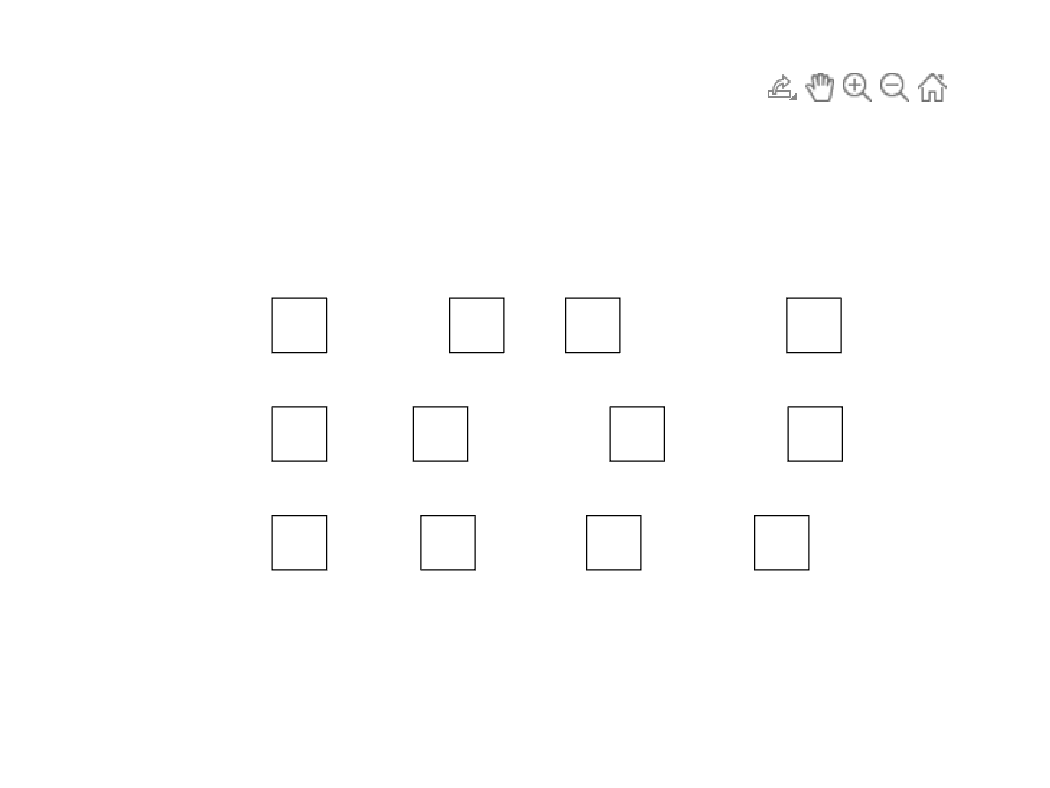

dof = 2:N;
ampl = zeros(N);
omega_sq = zeros(N, 1);
[ampl(dof, dof), omega_sq(dof, 1)] = eig(K(dof,dof), M(dof,dof), 'vector');
animate_modes(N, dof, omega_sq, ampl);

### Free case

The mode that looks stationary in the animation, corresponds to rigid translation of all masses

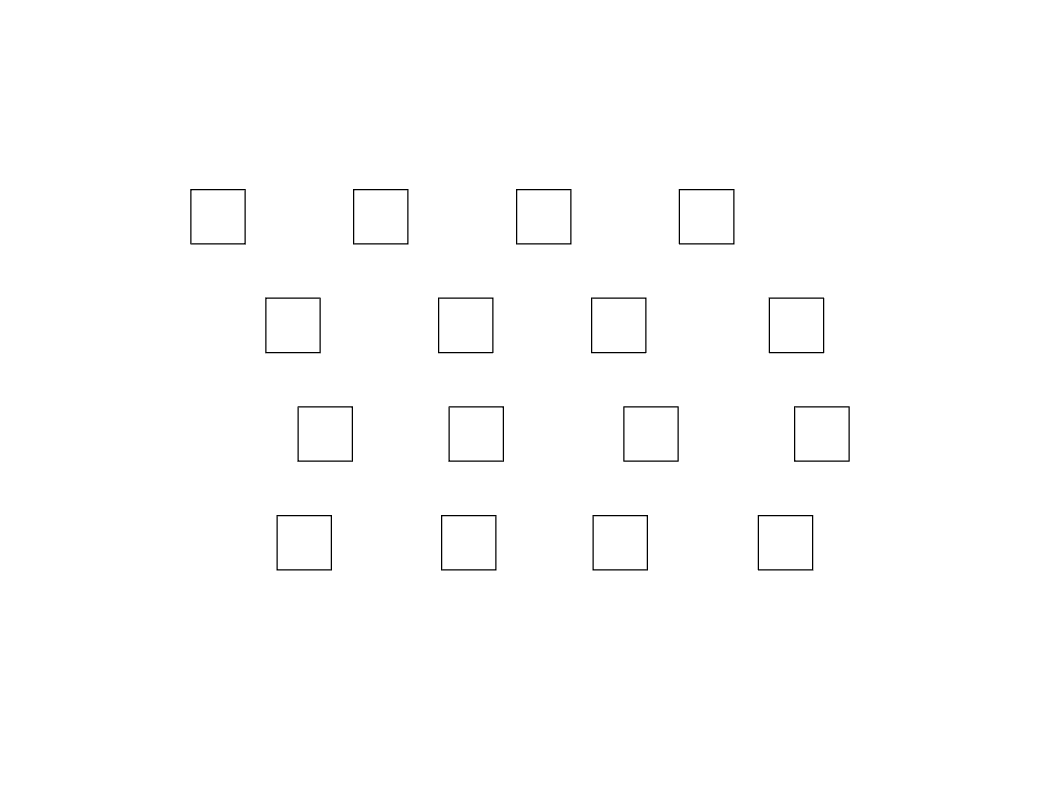

dof = 1:N;
ampl = zeros(N);
omega_sq = zeros(N, 1);
[ampl(dof, dof), omega_sq(dof, 1)] = eig(K(dof,dof), M(dof,dof), 'vector');
animate_modes(N, dof, omega_sq, ampl);

function animate_modes(N, modes, omega_sq, ampl)
figure;
anim_time = 3.0;
fps = 60;
mass_size = 1;
h_spacing = 3;
v_spacing = 2;
axis([0 (N+1)*h_spacing 0 (N+1)*v_spacing])
daspect([1 1 1])
axis off
% create rectangle for each mass
for mode=modes
    for mass=1:N
        masses(mode,mass) = rectangle();
    end
end
% animate
for t=1:(fps * anim_time)
    for mode=modes
        for mass=1:N
            x = mass * h_spacing - mass_size/2;
            if omega_sq(mode) > 0.001
                x = x + sin(t/fps * sqrt(omega_sq(mode, 1))) * ampl(mode, mass);
            else  % translation
                x = x + t/fps * ampl(mode);
            end
            y = (N+1-mode) * v_spacing - mass_size/2;
            masses(mode,mass).Position = [x y mass_size mass_size];
        end
    end
    drawnow
    pause(1/fps)
end
end